map = [];
% negro ->rojo
n = 10;
for i=1:n
    map = [map;[i/n,0,0]];
end

% rojo -> azul
for i=1:n
    map = [map;[1-i/n,0,i/n]];
end
% azul -> aguamarina
for i=1:n
    map = [map;[0,i/n,1]];
end

% aguamarina->verde
for i=1:n
    map = [map;[0,1,1-i/n]];
end
% verde->amarillo
for i=1:n
    map = [map;[i/n,1,0]];
end




clc

I = [0.73:0.0003:0.921]

I =     0.7300    0.7303    0.7306    0.7309    0.7312    0.7315    0.7318    0.7321    0.7324    0.7327    0.7330    0.7333    0.7336    0.7339    0.7342    0.7345    0.7348    0.7351    0.7354    0.7357    0.7360    0.7363    0.7366    0.7369    0.7372    0.7375    0.7378    0.7381    0.7384    0.7387    0.7390    0.7393    0.7396    0.7399    0.7402    0.7405    0.7408    0.7411    0.7414    0.7417    0.7420    0.7423    0.7426    0.7429    0.7432    0.7435    0.7438    0.7441    0.7444    0.7447


LI = length(I);
v = VideoWriter('Julia4.avi');
v.FrameRate = 24;
v.Quality = 100;


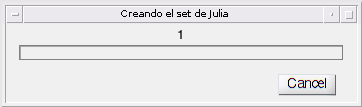

f = waitbar(0,'1','Name','Creando el set de Julia','CreateCancelBtn','setappdata    (gcbf,''canceling'',1)');

clc
open(v);



for h=1:(LI)
    waitbar(h/LI,f,sprintf('%0.5f',h/LI));
    W = f_julia_set(0.3+(1i*I(h)),4);
    imshow(W);
    colormap(map);
    F = getframe(gcf);
    writeVideo(v, F);
end

close(v);


